# Whole-recording dF/F0 and opto targets

Runs the live function WN_dFF_live: dF/F0 for every ROI, matching of each opto target to an ROI, and a trace for each target ROI. Figures appear inline (View tab: Output Inline / Output on Right). To zoom into a trace, click "Open in figure window" at the top-right of the figure.

## Settings

Change these, then run all (F5) or one section at a time (Ctrl+Enter).

dataPath     = 'D:\Data\CBLN4-ChRmine\processedData\20261005_mAK02\Recording1\TSeries-10052026-mAK02-LH-cbln4-G6sflxchrmine-influence-5HzWN-1067';
F0Window     = 30;          % s, sliding window for the baseline
F0Percentile = 10;          % percentile of F in that window used as F0
TargetROI    = [7 124];     % manual target -> ROI matches [target roi; ...]; [] = all automatic
ControlTarget = 1;          % vertical lines in the traces mark this target's stims

## Compute dF/F0 and match targets to ROIs

Shows the FOV: gray ROIs, red target circles, matched ROI in orange.

    Target    ROI    AutoROI    nOverlapping    Distance_um    Manual    nStims
    ______    ___    _______    ____________    ___________    ______    ______

      1         1        1           1              6.7        false      147  
      2         2        2           3              1.8        false      148  
      3         3        3           1              5.3        false      149  
      4         4        4           1              0.8        false      149  
      7       124      114           2              5.9        true       149  



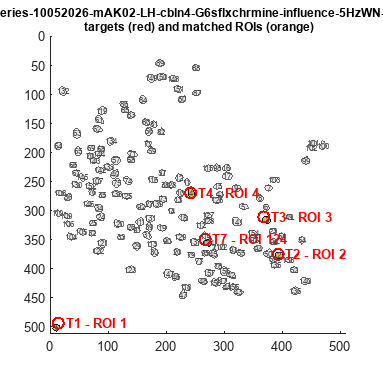

TSeries-10052026-mAK02-LH-cbln4-G6sflxchrmine-influence-5HzWN-1067: 158 ROIs, 21414 frames (2867 s), 742 opto stims, 5 targets


D =  WN_dFF_script(dataPath, 'F0Window', F0Window, 'F0Percentile', F0Percentile, 'TargetROI', TargetROI);

D.targetTable

ans = 5×7 table
    Target    ROI    AutoROI    nOverlapping    Distance_um    Manual    nStims
    ______    ___    _______    ____________    ___________    ______    ______

      1         1        1           1              6.7        false      147  
      2         2        2           3              1.8        false      148  
      3         3        3           1              5.3        false      149  
      4         4        4           1              0.8        false      149  
      7       124      114           2              5.9        true       149  


## Target ROI traces

Black = dF/F0; blue lines = control-target stims; ticks along the top = all opto stims, coloured by target.

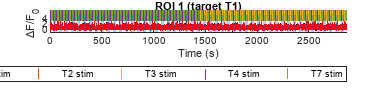

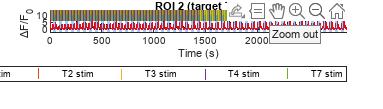

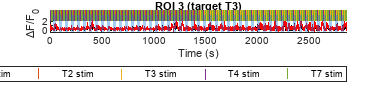

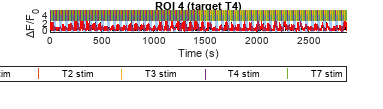

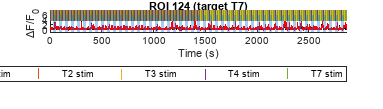

for k = 1:height(D.targetTable)
    ax = plot_ROI_trace(D, D.targetTable.ROI(k), 'ControlTarget', ControlTarget);
    title(ax, sprintf('ROI %d (target T%d)', D.targetTable.ROI(k), D.targetTable.Target(k)));
end

## Heatmaps of Nontargets?

## Any other ROI

Put the ROI numbers you want to look at here.

otherROIs = [10 50];
for r = otherROIs
    plot_ROI_trace(D, r, 'ControlTarget', ControlTarget);
end